## Projekt Grupowy- Grupa 13

## Algorytm A*

### Kosma Jagodziński

### Aleksandra Wardaszka

### Przemysław Kobylański

% Implementacja grafu, macierz sąsiedztwa
%               A B C D E F G H
graph_matrix = [0 1 0 0 0 0 0 0  %A -1
                1 0 0 1 1 0 0 0  %B -2
                0 0 0 1 0 0 1 0  %C -3
                0 1 1 0 1 0 1 0  %D -4
                0 1 0 1 0 1 0 0  %E -5
                0 0 0 0 1 0 0 1  %F -6
                0 0 1 1 0 0 0 1  %G -7
                0 0 0 0 0 1 1 0  %H -8
               ];
g=graph(graph_matrix,{'A','B','C','D','E','F','G','H',})

g =   graph with properties:

    Edges: [10×2 table]
    Nodes: [8×1 table]


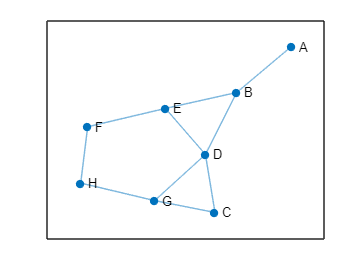

plot(g)

% Macierz zawierająca współrzędne wierzchołków. Kolejny wiersz to kolejny
% wierchołek.
vertices = [50,80;    %A
            195,185;  %B
            195,45;   %C
            300,115;  %D
            325,285;  %E
            425,207;  %F
            448,62;   %G
            600,155;
            ];

% Parametry liczone podczas wykonywania algorytmu.
g = ones(1,length(graph_matrix)).*inf;
f = ones(1,length(graph_matrix)).*inf;

% Wierzchołek startowy i końcowy.
start = 1;
meta = 8;

% Najkrótsza droga.
rout = A_asterix(start, meta, graph_matrix, vertices, g, f)

rout =      1     2     4     7     8


Liczenie heurystyki euklidesowej.

function [length] = calculate_heuristic(p1)
    length = sqrt((p1(1)^2)+(p1(2)^2));
end

Wyznaczanie z listy wierzchołka z najmniejszą wartością f.

function [lowest] = take_lowest_f_vertices(elements, f)
    lowest = length(elements) + 1;
    for ii=1:1:length(elements)
        if ii==1
            lowest=elements(ii);
        else
            if f(lowest) > f(elements(ii))
                lowest = elements(ii);
            end
        end
    end
end

Rekonstrukcja najkrótszej drogi między wierzchołkami grafu.

function [output_rout] = reconstruct(coming_from, meta, start)
    rout = [meta];
    while rout(end) ~= start
        rout(end+1) = coming_from(rout(end));
    end
    
    output_rout = fliplr(rout);
end
   

Implementacja algorytmu A*.

function [rout] = A_asterix(start, meta, graph_matrix, vertices, g, f)
    % wektor do zapisu drogi
    rout = [];
    
    % inicjalizacja zmiennych
    considered = start;
    coming_from = zeros(1,length(graph_matrix));
    g(start) = 0;
    f(start) = calculate_heuristic(vertices(start, :));

    % Pętla wykonuje się dopóki lista considered będzie zawierać
    % wierzchołki
    while considered
        x = take_lowest_f_vertices(considered, f);
        % Jeśli dotarto do mety następuje rekonstrukcja drogi
        if x == meta
            rout = reconstruct(coming_from, meta, start);
            break
        end
        considered = considered(find(considered ~= x));
        % Przeglądanie wszystkich sąsiadów wierzchołka x.
        % "y" to waga krawedzi, "i" to sąsiedni wierzchołek
        z = length(graph_matrix(x, :));
        for ii=1:1:length(graph_matrix(x, :))
            y = graph_matrix(x,ii);
            if y ~= 0
                temporary_g = g(x) + y;
                if temporary_g < g(ii)
                    coming_from(ii) = x;
                    g(ii) = temporary_g;
                    f(ii) = g(ii) + calculate_heuristic(vertices(ii, :));
                    if isempty(find(considered == ii))
                        considered(end+1) = ii;
                    end
                end
            end
        end
    end
end
